% dataProcessingTutorial.m
clear all; close all; clc;

## Pre-process raw BDF data

This is the first step in the processing chain. You need to take the raw continuous .bdf data, bandpass filter it, re-reference to the average of the Left and Right mastoid electrodes, remove eyeblink artifacts, epoch into individual trials, and baseline correct.

This step will also summarize the behavioral data, which will become useful in organizing the trials into the different experimental conditions using logical indexing (e.g. SCORE.attend==1)

I've since modified the processBDF() function to apply more generally to all sorts of EEG experiments. It now only returns the evoked response potentials. The behavioral data will not be summarized using a separate function

For the selective attention tasks, the stimulus period for all trials is marked by the event trigger, 9. The stimulus interval is 3 seconds in duration, so you'll want to epoch a little before (100 ms) and a little after (500 ms after the onset of the last stimulus token--arrow or tone). The bandpass filter cutoffs can now be set as a function input. Here we'll use 1-30 Hz. See 'help processBDF' for more info.

bdfFilename = '~/Documents/Binaural_Research/VisualFFR/rawDATA/VF000/VF000.bdf';
%   Note: you'll have to modify all the path and file names in this example 
%         to match where you have stored the relevant files.

trg = 9;
tEpo = [-0.100 2.750];
cf = [1 30];

ERP = processBDF(bdfFilename,trg,tEpo,cf)

Loading file: ~/Documents/Binaural_Research/VisualFFR/rawDATA/VF004/VF004.bdf...
32-channel setup...
Filtering data (1 to 30 Hz)...
Removing eyeblinks...
Epoching -0.100 sec to +2.750 sec...


ERP =                   subjID: 'VF004'
                     erp: [11674x37x180 double]
               trialType: [180x1 double]
                triggers: [11674x180 double]
                  diodes: [11674x4x180 double]
                       t: [1x11674 double]
             preStimTime: -0.1000
            postStimTime: 2.7500
                      fs: 4096
             eyeblinkRej: 1
    eyeblinkRejThreshold: 95.1457
      baselineCorrection: 0
               filterObj: [1x8193 double]
           filterCutOffs: [1 30]
             bdfFilename: '~/Documents/Binaural_Research/VisualFFR/rawDATA/VF004/VF004.bdf'
          dataDimensions: '[n x channels x trials]'


## To epoch based on multiple event triggers

For experiments for which you have multiple trigger events to delineate the different trial types, you can enter in the triggers of interest as a vector of trigger values. The presentation order of the different trial types are preserved and returned as ERP.triggers.

You can apply the processBDF() function to the simple tone pip oddball experiment using the following parameters:

bdfFilename2 = '../rawDATA/GK000/GK000.bdf';
trg2 = [1 2]; % 1=standard tone event trigger, 2=deviant tone event trigger
tEpo2 = [-0.100 0.500]; % -100 to 500 ms

ERP2 = processBDF(bdfFilename2,trg2,tEpo2);
% Note: if you leave off the last input, cf, it will default to passband
%       cutoff frequencyes of 1-30 Hz.

## Summarizing the behavioral data

For the selective attention experiments, you can gather the behavioral data using the following:

matFilename = '~/Documents/Binaural_Research/VisualFFR/rawDATA/VF000/VF000_20160218_1502_RESULTS.mat';
% This file is on the Stimulus Presentation Computer.

SCORE = getBehavior(matFilename)

SCORE =         subjID: 'VF004'
       TotalPC: 0.4833
    perblockPC: [0.3333 0.3333 0.3333 0.3333 0.3333 0.3333 0.3333 0.5556 0.9444 1]
        attend: [18x10 double]
      stimIsLR: [18x10 double]
          answ: [18x10 double]
          resp: [18x10 double]
          hits: [18x10 logical]
            FA: [18x10 logical]
            NR: [18x10 logical]
        FArate: 0
        NRrate: 0.7750
      attLeadL: [18x10 logical]
      attLeadR: [18x10 logical]
       attLagL: [18x10 logical]
       attLagR: [18x10 logical]
    attPassive: [18x10 logical]
     startTime: {1x10 cell}
      stopTime: {1x10 cell}


## Manipulating the data using logical indexing

Because the data in the ERP structure is a trial-by-trial description of the experiemental session, you'll have to use logical indexing to sort the ERP data into your desired conditions.

% Let's say I want to collect only the trials where the subject was
% attending the LEADING stream when it was presented on the LEFT.
% Additionally, let's only gather the 32 scalp electrode signals

attLeadL = ERP.erp(:,1:32,SCORE.attLeadL);

% Taking this concept one step further, let's collect the trials where the
% subject was attending the LAGGING stream on the RIGHT only when they
% correctly identified the contour.

attLagR_hits = ERP.erp(:,1:32,(SCORE.attLeadL & SCORE.hits));

## Visualizing the epoched data

You're now ready to start looking at the multi-channel data. Let's start with looking at two different channels with the three different attentional conditions (1: attend lead/left, 2: passive, 3: attend lag/right). We'll plot the across trial average ERPs (evoked response potentials)

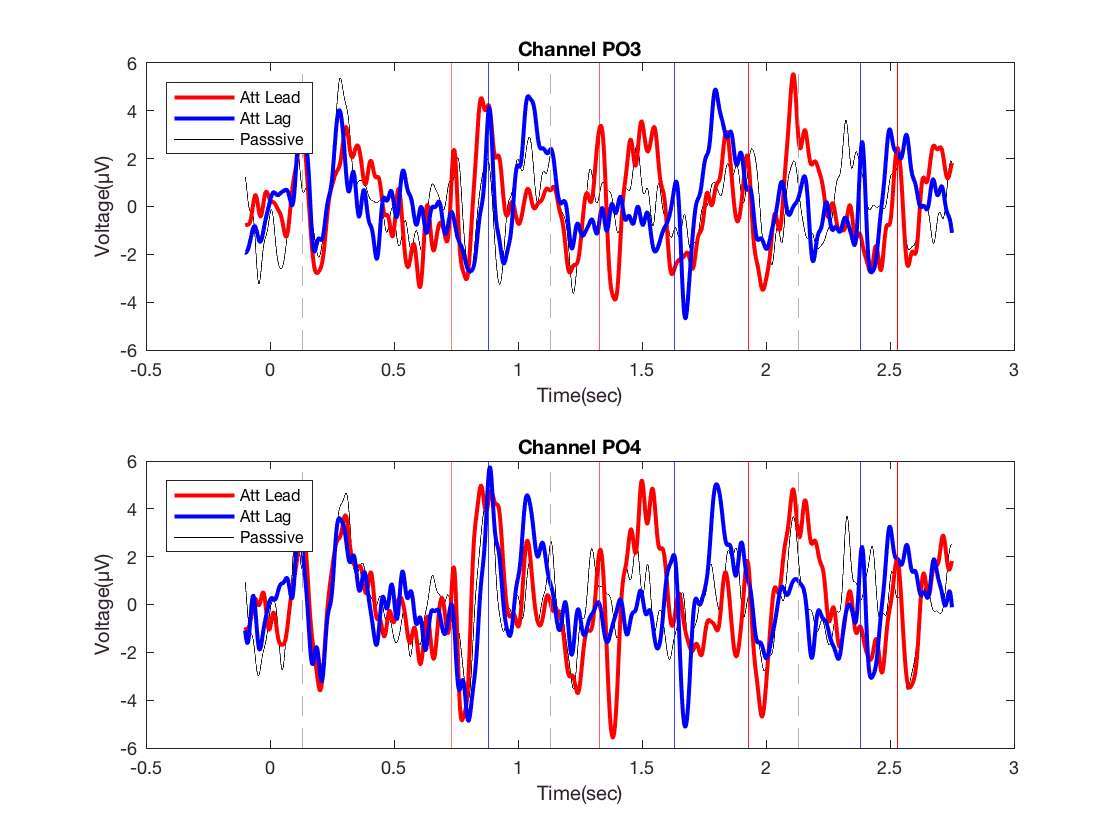

load chanlocs32.mat; % .mat file with relevant electrode locations and labels
                     % We'll use this in a lot of the data visualizations

f1 = figure;
subplot(2,1,1); % 2 row x 1 column subplot, top subplot
p12 = plot(ERP.t,mean(ERP.erp(:,14,SCORE.attPassive),3),'k');
hold on;
p11 = plot(ERP.t,mean(ERP.erp(:,14,SCORE.attLeadL),3),'r','LineWidth',2);
p13 = plot(ERP.t,mean(ERP.erp(:,14,SCORE.attLagR),3),'b','LineWidth',2);
xlabel('Time(sec)'); ylabel('Voltage(µV)');
plotN100Lines(0.130); % puts vertical lines at expected onset response
                      % here, 130 ms after stimulus onset
legend([p11 p13 p12],'Att Lead','Att Lag','Passsive','Location','NorthWest');
title(sprintf('Channel %s',chanlocs(14).labels));
                      
subplot(2,1,2); % 2 row x 1 column subplot, bottom subplot
p22 = plot(ERP.t,mean(ERP.erp(:,18,SCORE.attPassive),3),'k');
hold on;
p21 = plot(ERP.t,mean(ERP.erp(:,18,SCORE.attLeadL),3),'r','LineWidth',2);
p23 = plot(ERP.t,mean(ERP.erp(:,18,SCORE.attLagR),3),'b','LineWidth',2);
xlabel('Time(sec)'); ylabel('Voltage(µV)');
plotN100Lines(0.130);
legend([p21 p23 p22],'Att Lead','Att Lag','Passsive','Location','NorthWest');
title(sprintf('Channel %s',chanlocs(18).labels));

## Looking at the data across the entire scalp

Generally, auditory evoked responses are centered around Cz-Fz and visual evoked responses are located around the parietal and occipital electrodes. However, resist the urge to limit your search to only these regions. You need to visualize your data as an entire set. Here, I'm going to use some EEGLab functions to help me do just that.

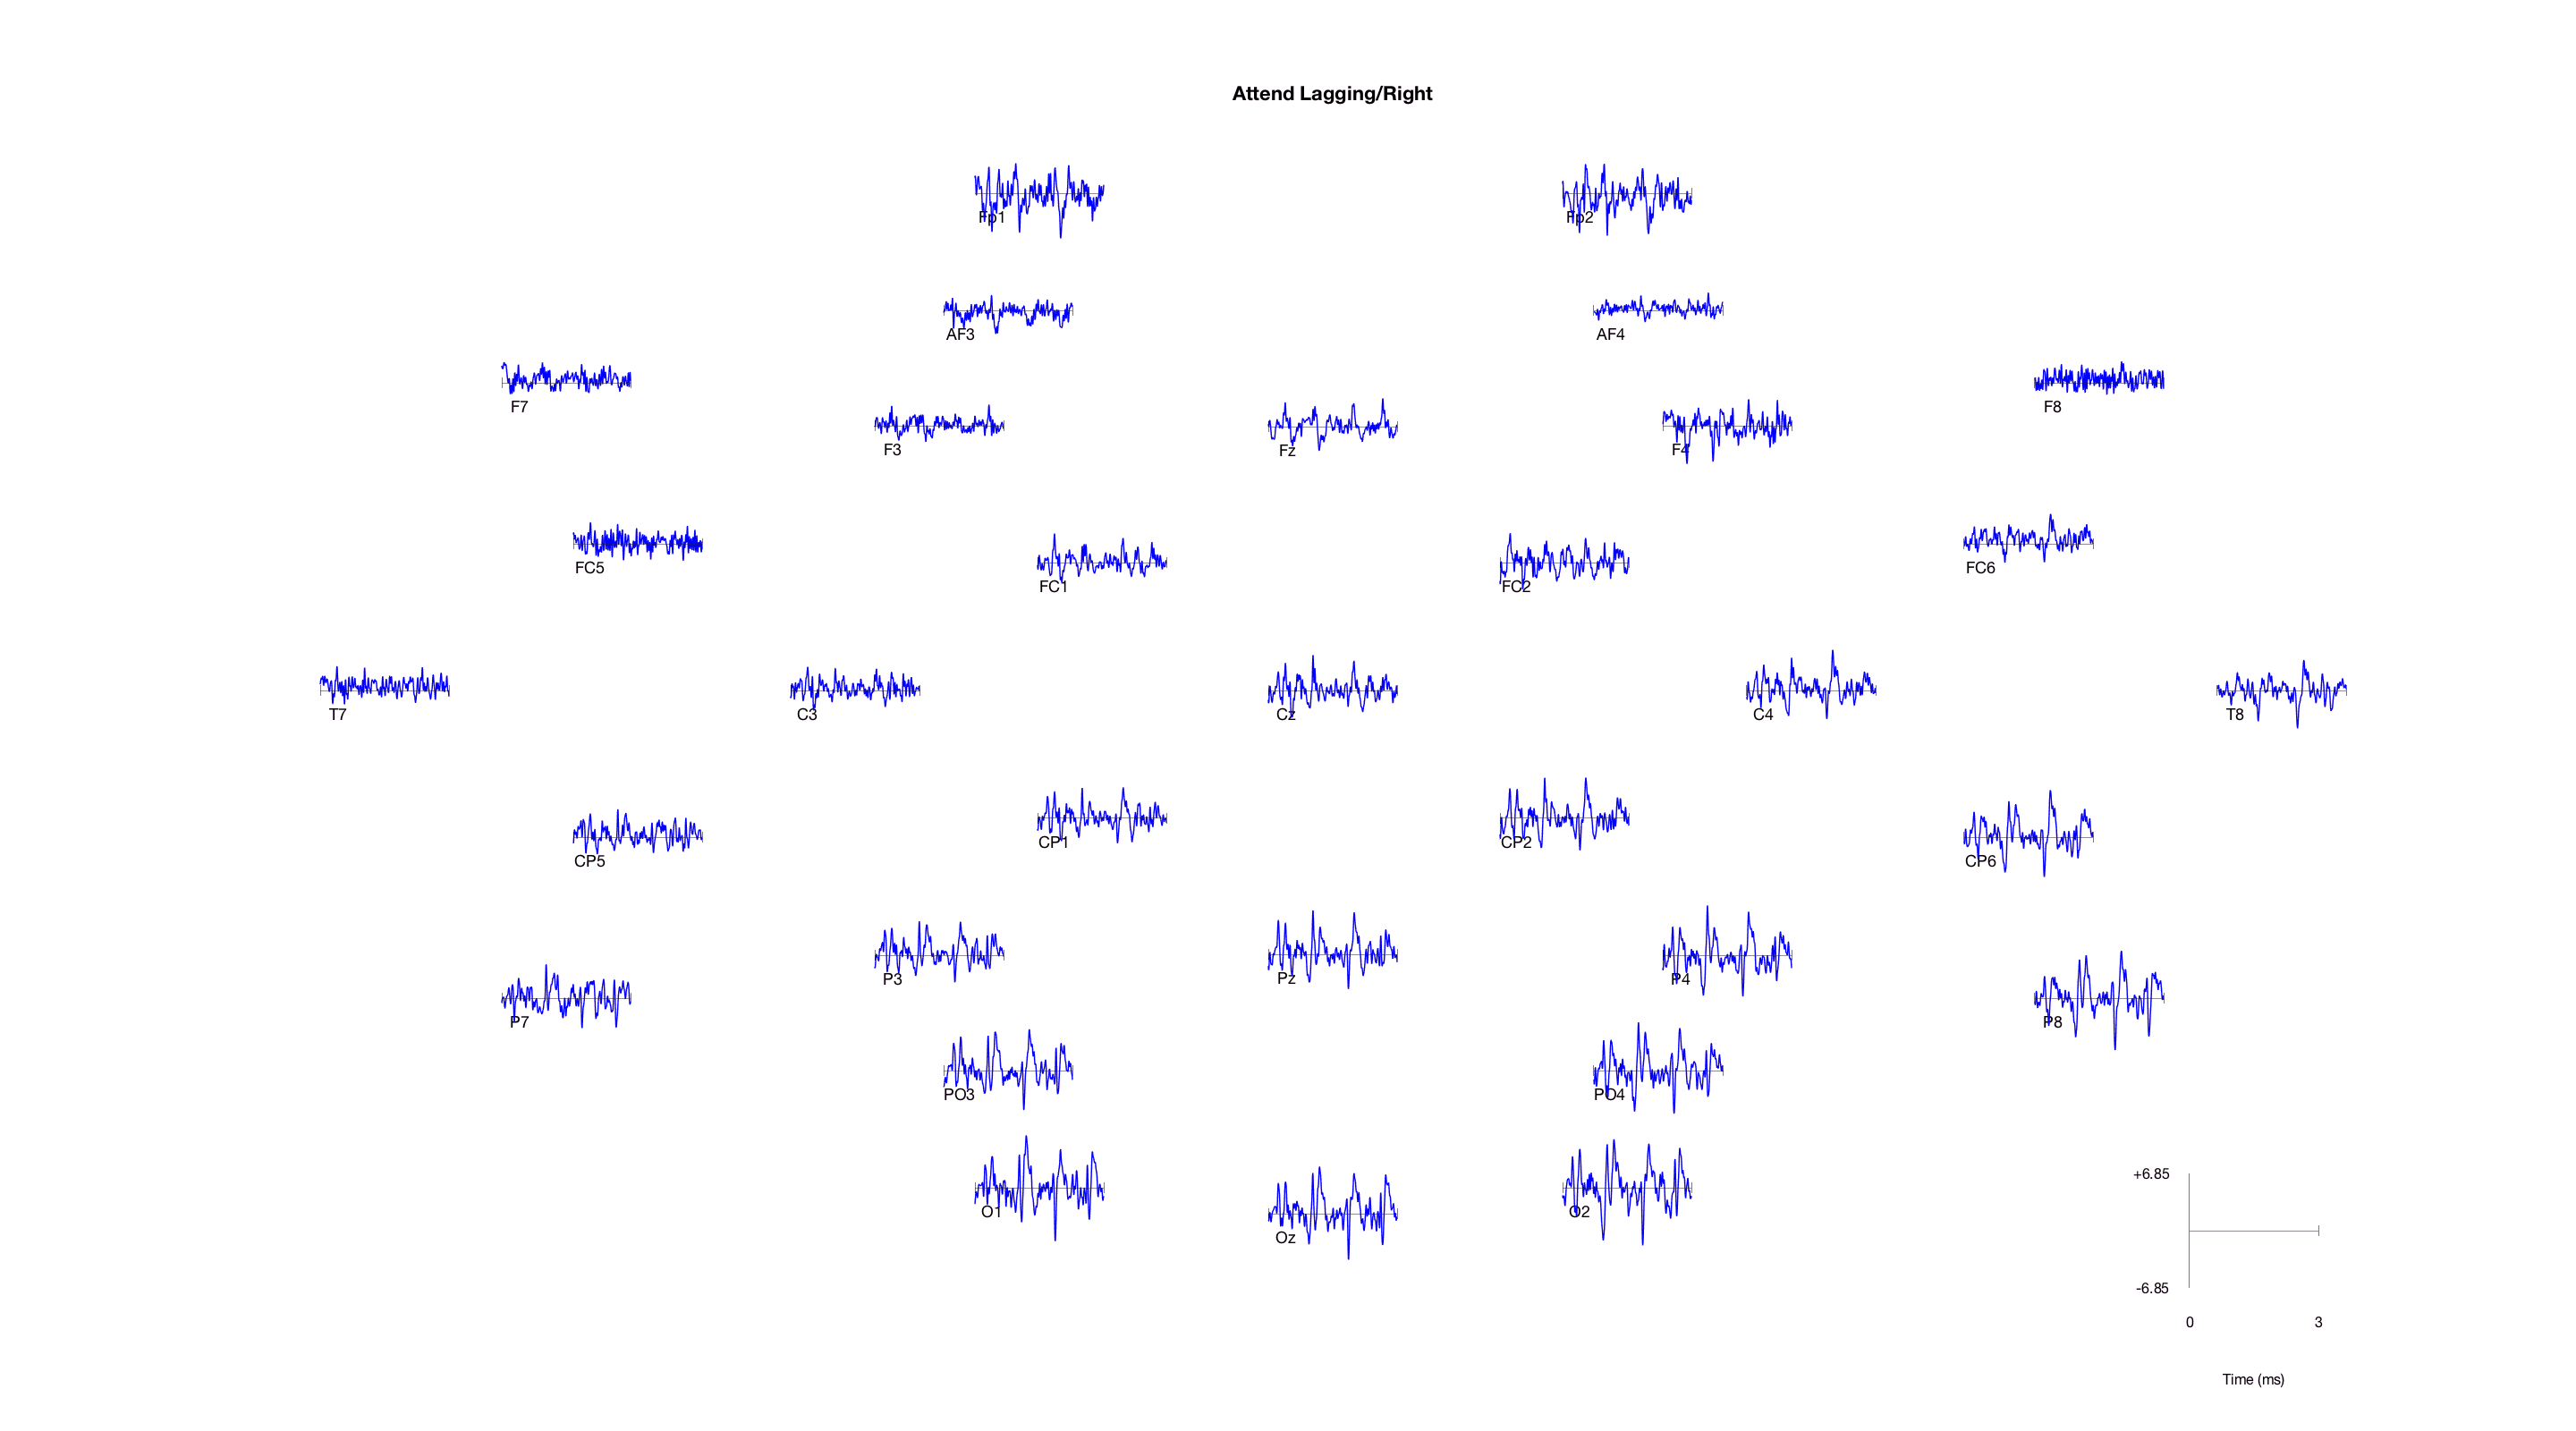

Plotting data using axis size [0.05,0.08]
limits: [xmin,xmax,ymin,ymax] = [ 0.1  2.8 -6.85 6.85]
Plotting 1 traces of 11674 frames with colors: 'b' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32


%   First, I need to add the appropriate directories into my working path.
addpath ~/Documents/MATLAB/eeglab13_4_4b/functions/timefreqfunc/;
addpath ~/Documents/MATLAB/eeglab13_4_4b/functions/sigprocfunc/;
addpath ~/Documents/MATLAB/eeglab13_4_4b/functions/adminfunc/;
addpath ~/Documents/MATLAB/eeglab13_4_4b/functions/guifunc/;
addpath ~/Documents/MATLAB/eeglab13_4_4b/functions/popfunc/;

%   We'll start with an easy case.  I'm only going to plot the "attend
%   lagging/right" condition.

f2 = figure;
set(f2,'Position',[1 5 1440 800]); % have the figure fill the screen
plottopo(mean(ERP.erp(:,1:32,SCORE.attLagR),3)',... % needs to be (channel x samples)
    'chanlocs',chanlocs,... % channel location information
    'frames',size(ERP.erp,1),... % number of samples per epoch
    'limits',[-ERP.preStimTime ERP.postStimTime 0 0],... % x- and y-limits
    'colors',{'b'},... % custom color assignment
    'legend',{'att lag R'},... % legend entries
    'ydir',1,... % negative is down, positive is up...AS IT SHOULD BE!!!
    'title',sprintf('Attend Lagging/Right'));


% You can now see all the ERPs in their approximate scalp locations.  To
% get a closer look, click on a channel plot to expand it.

## Plotting multiple ERPs on a single 'plottopo' figure

To get all three attentional conditions on the plot, you need to concatenate the data. (type: 'doc cat' on the command line for more info)

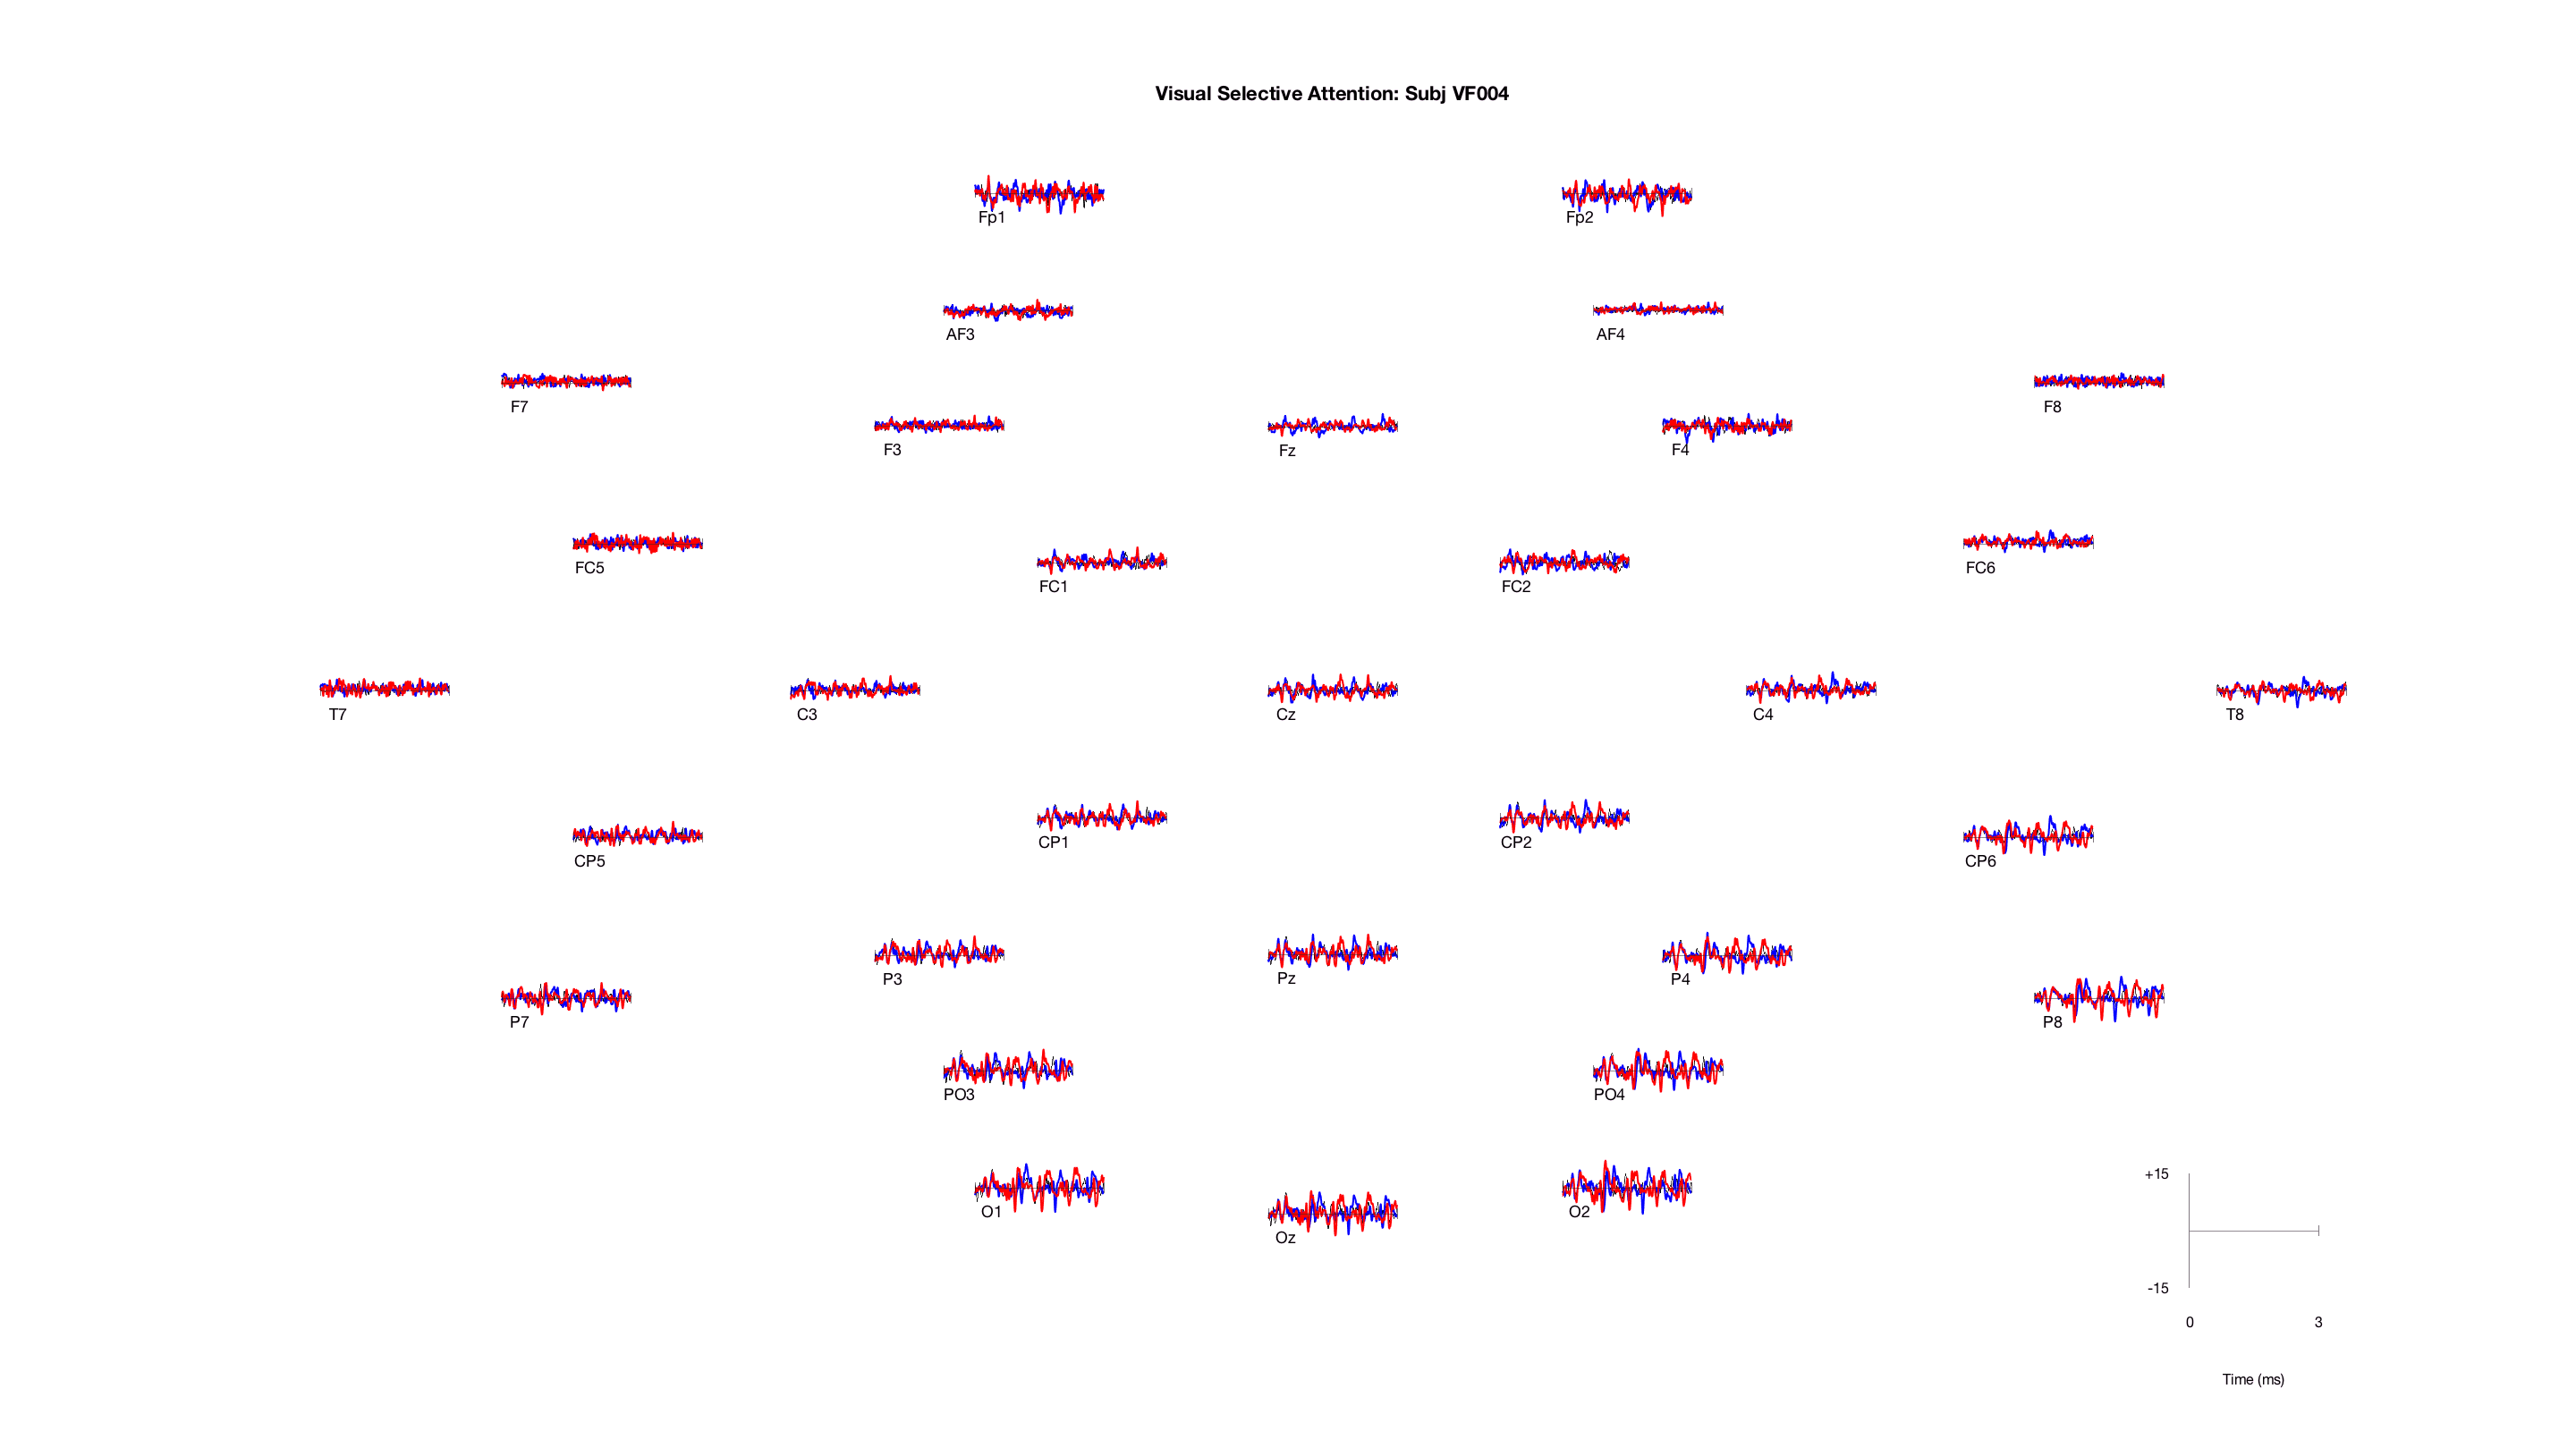

Plotting data using axis size [0.05,0.08]
limits: [xmin,xmax,ymin,ymax] = [ 0.1  2.8 -15.00 15.00]
Plotting 3 traces of 11674 frames with colors: 'k' 'b' 'r' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32
trace 2:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32
trace 3:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32


allDATA = cat(3,mean(ERP.erp(:,1:32,SCORE.attPassive),3)',...
                mean(ERP.erp(:,1:32,SCORE.attLagR),3)',...
                mean(ERP.erp(:,1:32,SCORE.attLeadL),3)');
            
YLIM = [-15 15]; % so I can easily change the y-axis limits

f3 = figure;
set(f3,'Position',[1 5 1440 800]); % have the figure fill the screen
plottopo(allDATA,...
    'chanlocs',chanlocs,... % channel location information
    'frames',size(ERP.erp,1),... % number of samples per epoch
    'limits',[-ERP.preStimTime ERP.postStimTime YLIM],... % x- and y-limits
    'colors',{{'k'},{'b','LineWidth',1},{'r','LineWidth',1}},... % custom color assignment
    'legend',{'Pass','Lag','Lead'},... % legend entries
    'ydir',1,... % negative is down, positive is up...AS IT SHOULD BE!!!
    'title',sprintf('Visual Selective Attention: Subj %s',ERP.subjID));

## Topoplot: a snapshot of scalp activity

Another very useful plot is the 'topoplot', which is a plot of the scalp voltages at a single time point with the voltages represented by hot and cold colors for positive and negative voltages, respectively.

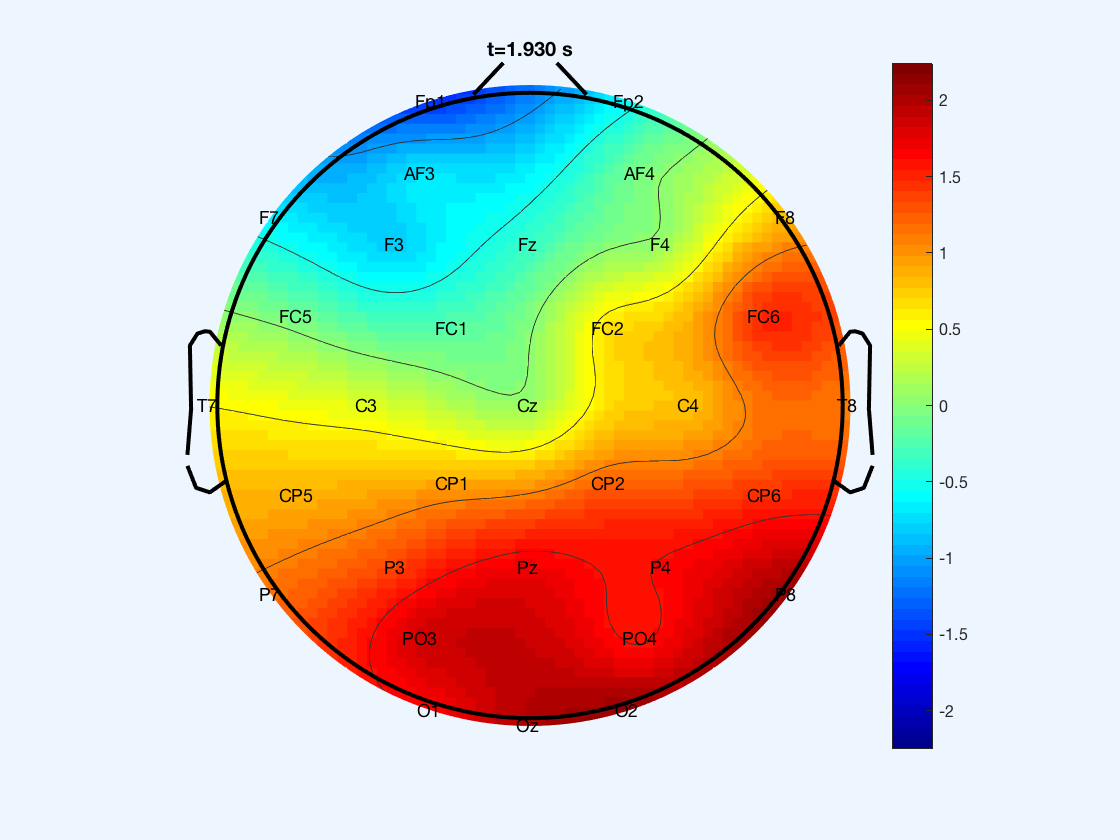

f4 = figure;
t1 = 3*0.600+0.130; % pick a time point to look at
tk = find(ERP.t<=t1,1,'last'); % locate the appropriate time sample

topoplot(mean(ERP.erp(tk,1:32,SCORE.attLeadL),3)',... % the data
        chanlocs,'electrodes','labels'); % show electrode by 10-20 label
colorbar; % show the colorbar legend
title(sprintf('t=%1.3f s',ERP.t(tk)));
set(f4,'Name','Attend Lead Left');

## Many topoplots!

A very useful way to visualize the data in topoplot form is to create a time series in multiple subplot sections

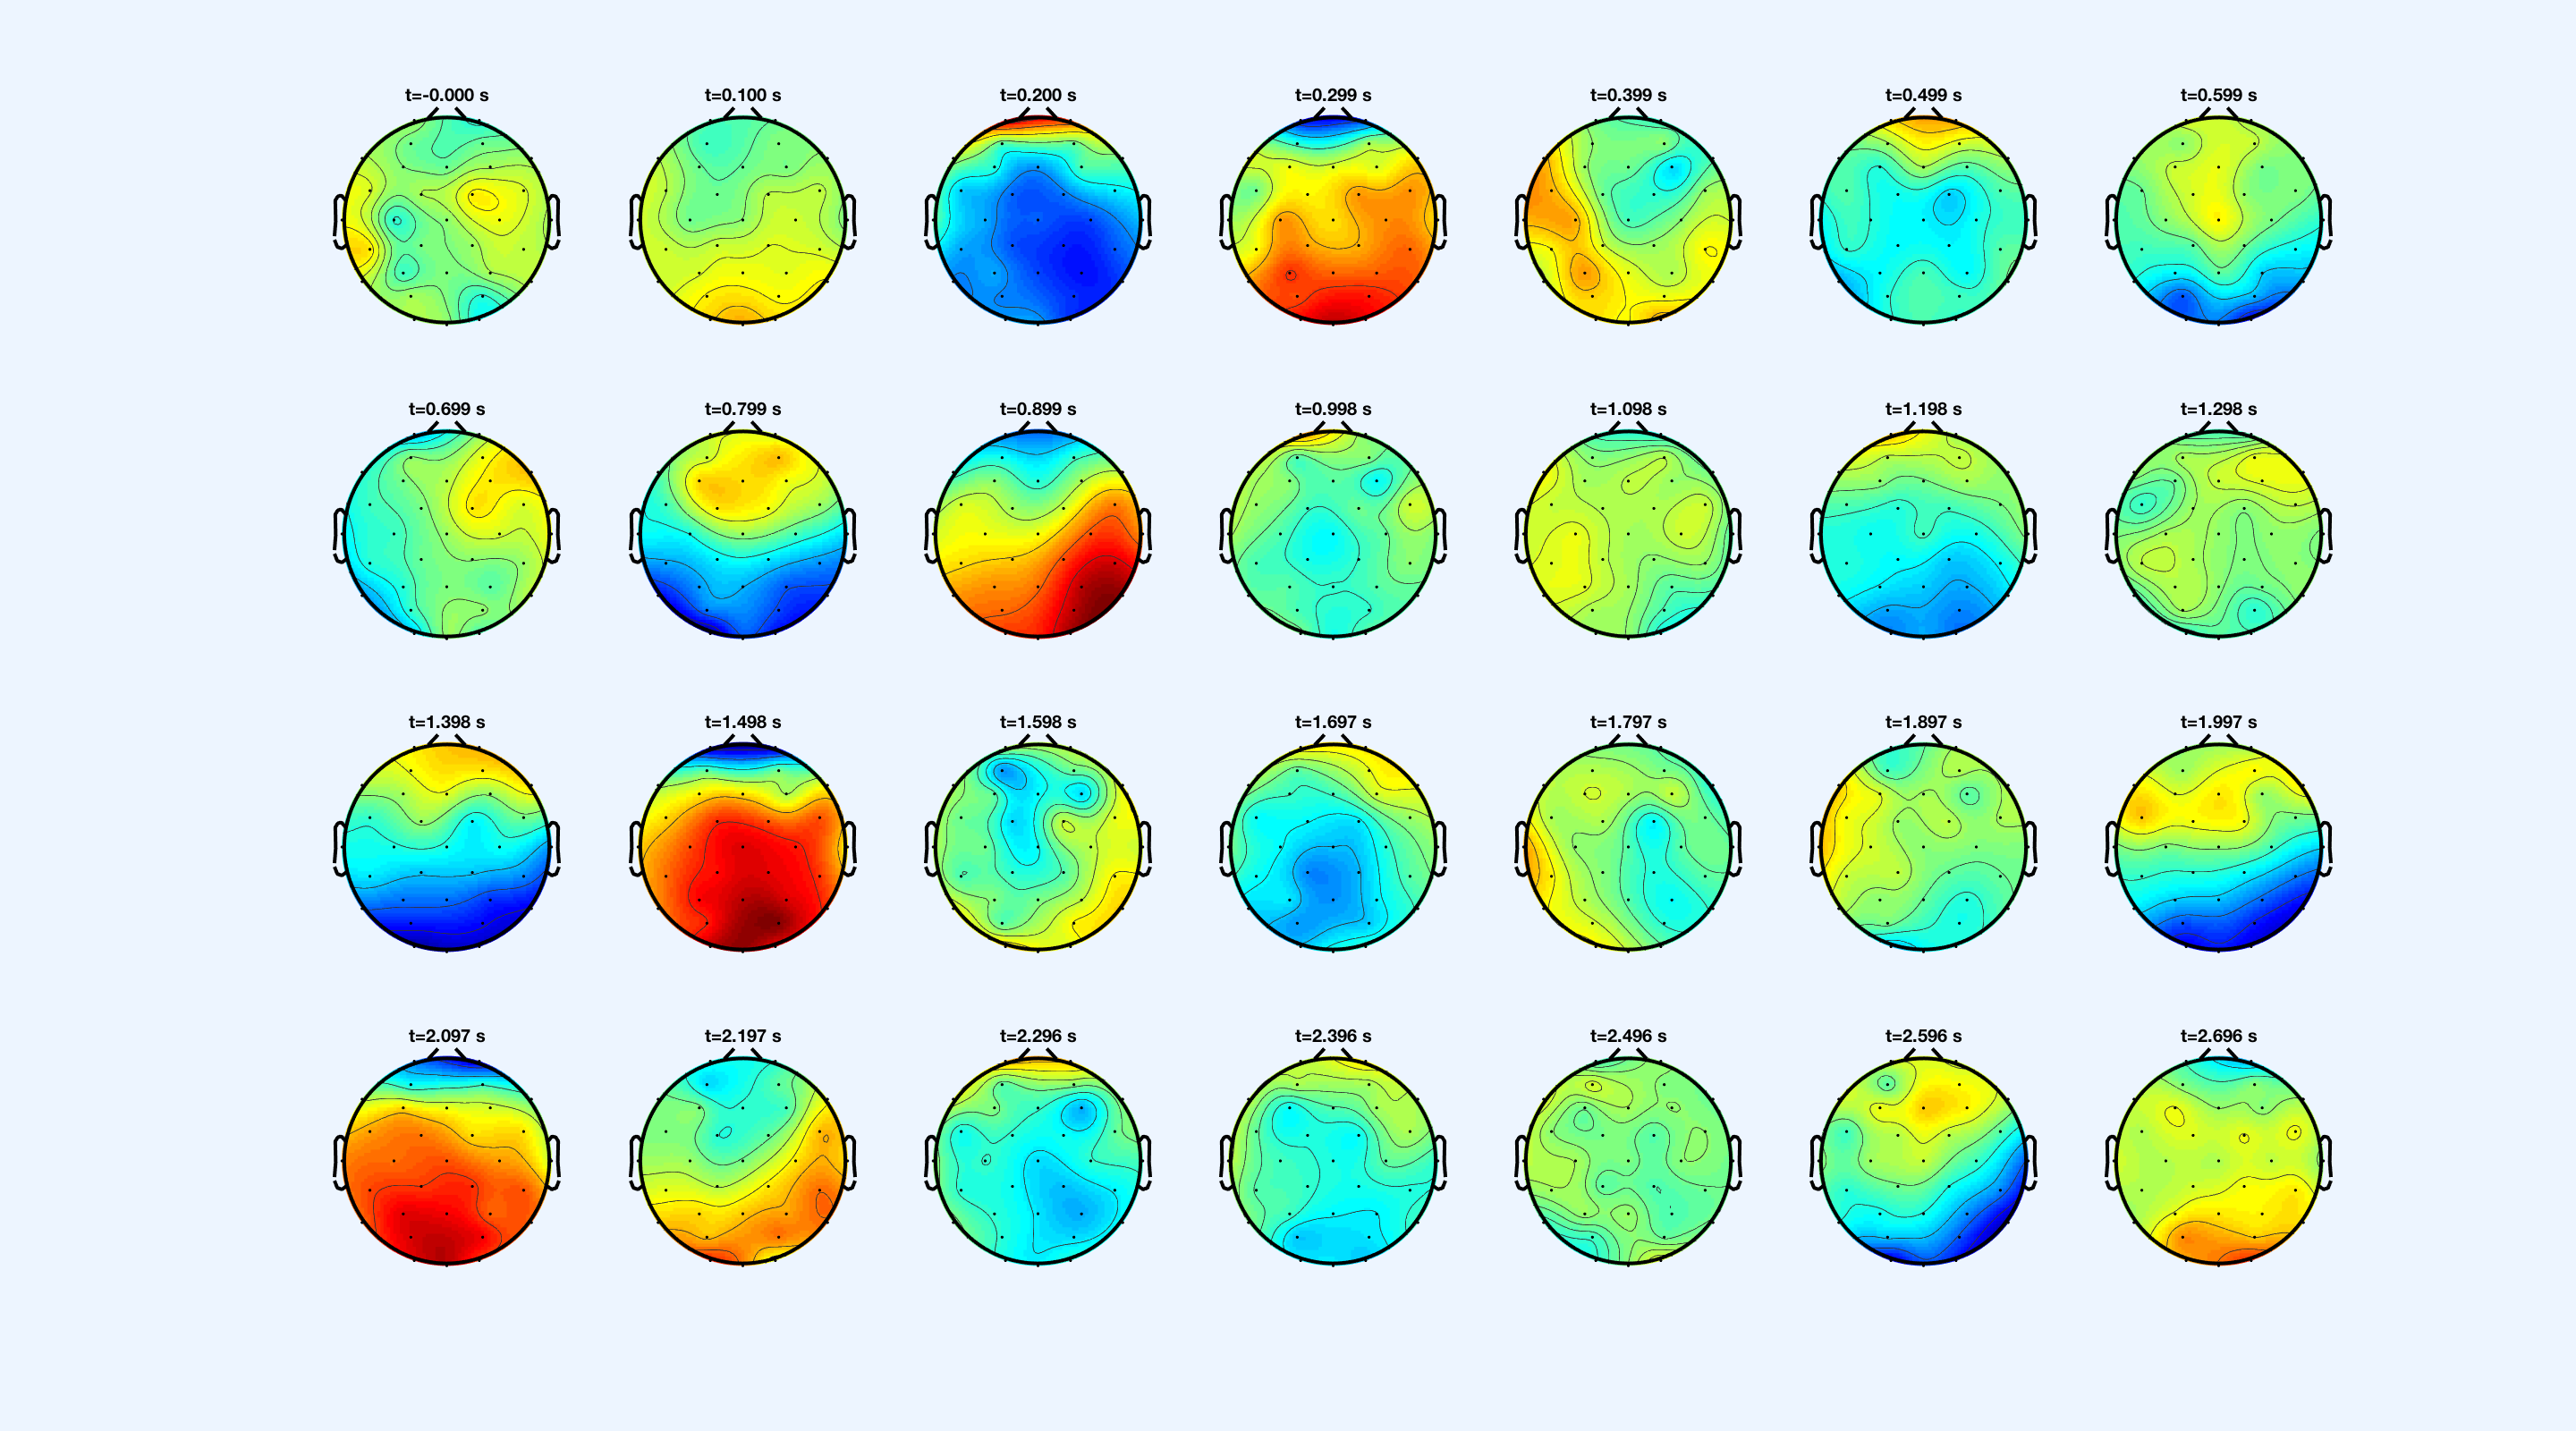

%   Let's look at the data every 100 ms.
t0 = find(ERP.t<=0,1,'last');
dn = fix(0.100*ERP.fs); % number of samples between time steps
N = t0:dn:size(ERP.erp,1); % start at t=0 and go to end of trial epoch

f5 = figure;
set(f5,'Position',[1 5 1440 800],'Name','Attend Lead Left');

for n = 1:size(N,2)
    subplot(4,7,n);
    topoplot(mean(ERP.erp(N(n),1:32,SCORE.attLeadL),3)',... % the data
        chanlocs,'electrodes','on',...  % show electrodes as points
        'maplimits',[-5 5]); % we'll set the y-axis range to ±5 µV, see above
    title(sprintf('t=%1.3f s',ERP.t(N(n))));
end